#  Broadband tutorial

## Summary

Simulate an LFP time series and then evaluate it using our broadband extraction method. We simulate the LFP time series in 3 steps: 

- There is an underlying, noiseless time series, which can be thought of as the idealized rate of spike arrivals per neuron

- We generate noisy samples scaled to this rate, which can be thought of as a poisson-like nonlinearitiy defining the spike arrivals

- We temporally integrate the noisy time series, which can be thought of as the dendritic integration of the currents arising from spike arrivals

After generating multiple noisy time series with the identical underlying time-varying rate, we analyze the time series by extracting the broadband envelope in each trial using one of several algorithms. We then average the envelopes across trials computed by each algorithm, and compare these time-varying broadband envelopes to the noiseless time-varying rate used to seed the time series. Ideally, the broadband envelope be similar to the rate. That is, we hope to get out what we put in.

There are several options for the noiseless time series, including a step, a pulse, a sine wave, etc.

Some useful references:

[http://chrisholdgraf.com/extracting-high-frequency-signals-for-electrocorticography/](http://chrisholdgraf.com/extracting-high-frequency-signals-for-electrocorticography/)

[https://www.ncbi.nlm.nih.gov/pubmed/15262077](https://www.ncbi.nlm.nih.gov/pubmed/15262077)

[http://journals.plos.org/ploscompbiol/article?id=10.1371/journal.pcbi.1002655#s4](http://journals.plos.org/ploscompbiol/article?id=10.1371/journal.pcbi.1002655#s4)

[http://www.sciencedirect.com/science/article/pii/S0896627312007179](http://www.sciencedirect.com/science/article/pii/S0896627312007179)

## Example

% Run the script several times, changing the response profile each time
% responses = {'step' 'pulse' 'bump' 'square' 'sine' 'noise'};
% for ii = 1:length(responses)
%   resp = responses{ii};
%   t_broadband;
% end


## Settings

% Choose the reponse profile, noise type, and intgreation method

% The response defines the noiseless, time-varying rate [default = 'step']
responses = {'boxcar' 'steps' 'step' 'pulse' 'bump' 'square' 'sine' 'noise' 'pred dn'};
%if ~exist('resp', 'var') || isempty(resp), resp = responses{2}; end
resp = responses{2};

srate  = 1000;  % sample rate (Hz)
n      = 100;   % number of repeated trials
t      = (-1999.5:1999.5)'/srate; % trials are -2 to 2 seconds, and later clipped to [0 1] to avoid edge artifacts
nt     = length(t);  % number of time points

% frequency bands for extracting broadband
bands = {[70 170], 10}; % {[lower bound,  upper bound], window sz}

% for plotting
fontsz = 18;
lw = 3;

## Generate noiseless time course

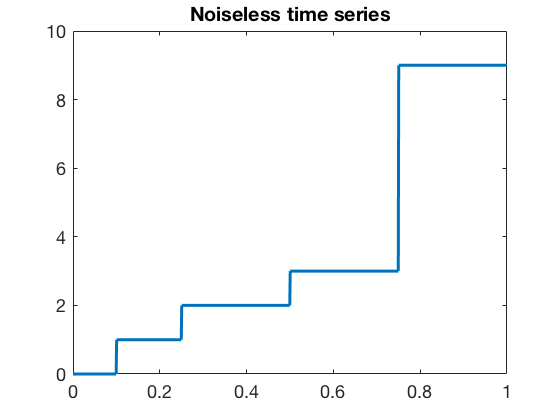

% This is the idealized input spike rate as a function of time, expressed in spikes per time bin

spikeRate      = zeros(size(t));

switch resp
    case 'boxcar'
        spikeRate(t>.2 & t < .7) = 1;
        xl = [0 1];
        
    case 'pulse'
        spikeRate(t>.5 & t < .51) = 1;
        xl = [.4 0.6];
        
    case 'step'
        spikeRate(t>0.5) = 1;
        spikeRate = spikeRate + 1;
        xl = [0.4 0.6];
        
    case 'steps'
        spikeRate(t>0.1)   = 1;
        spikeRate(t>0.25)  = 2;
        spikeRate(t>.5)    = 3;
        spikeRate(t>.75)   = 9;
        xl = [0 1];
        
    case 'bump'
        t1  = 0.500; sigma = .030;
        gau = exp(-(t-t1).^2/(2*sigma^2));
        spikeRate   = gau + 1;
        xl = [.25 0.75];
        
    case 'square'
        spikeRate = square(2*pi*t*3)+2;
        xl = [.2 0.8];
        
    case 'sine'
        spikeRate = sin(2*pi*t*3)+2;
        xl = [.2 0.8];
        
    case 'noise'
        spikeRate = smooth(rand(size(t)), 50);
        xl = [0 .5];
        
    case 'pred dn'
        tmp = load('predDn.mat', 'predDn');
        spikeRate = tmp.predDn;
        xl = [0 1];
        
end

% Plot the noiseless time series
figure();
plot(t, spikeRate, 'LineWidth', lw);
title('Noiseless time series')
set(gca, 'XLim', xl, 'FontSize', fontsz)

## Generate multiple noisy time series

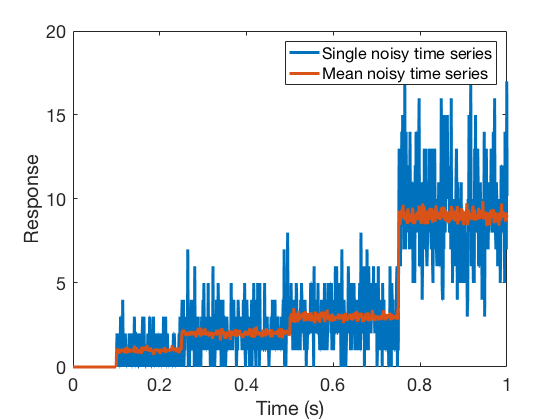

% Generate multiple time series using poisson sampling at the time-varying rate determined above
spikeArrivals = poissrnd(repmat(spikeRate, [1 n]));

figure,
plot(t, spikeArrivals(:,1), t, mean(spikeArrivals,2), 'LineWidth', lw);
set(gca, 'FontSize', fontsz, 'XLim', xl)

legend('Single noisy time series', 'Mean noisy time series')
xlabel('Time (s)')
ylabel('Response')

## Integrate noisy time series

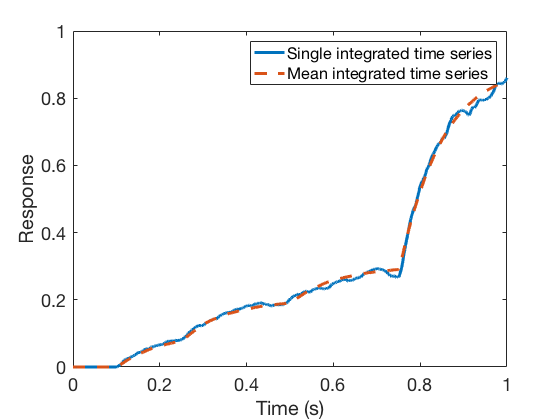

% Simulate leaky integration in the dendrite to generate time-varying dendritic currents

alpha = 0.1;    % time constant for dendritic leakage

tau   = 0.0023; % time constant for post-synaptic current

dt = 1/srate;   % time step for simulations

% Post-synaptic current impulse response function. This current (multiplied by
% the synaptic weight) is initiated each time a spike arrives. It rises quickly and falls
% slowly. Normalize it to sum of 1.
psc = exp(-1/tau*(0:dt:.100))'; psc = psc / sum(psc);

% post-synaptic current (Q)
Q = conv2(spikeArrivals, psc, 'full')  ;
Q = Q(1:size(spikeArrivals, 1), :);

% alternatively, don't model the post-synaptic currents
% Q = spikeArrivals;

% The leakage current (I) is proportional to the accumulated charge
I = zeros(size(spikeArrivals));
I(1,:) = spikeArrivals(1,:);
for ii = 1:length(t)-1
    
    dIdt =  (-I(ii,:)/alpha +  Q(ii,:) );
    
    dI   = dIdt * dt;
    
    I(ii+1,:) = I(ii,:) + dI;
end

figure,
plot(t, I(:,1), t, mean(I,2), '--', 'LineWidth', lw);
set(gca, 'FontSize', fontsz, 'XLim', xl)

legend('Single integrated time series', 'Mean integrated time series')
xlabel('Time (s)')
ylabel('Response')

## Amplifier output

noise = randn(size(I))*std(I(:))*.01;
A = I + noise*0;

## Compute broadband using 6 different methods


[broadband{1}, str{1}] = extractBroadband(A(:), srate, 1, bands);
[broadband{2}, str{2}] = extractBroadband(A(:), srate, 2, bands);
[broadband{3}, str{3}] = extractBroadband(A(:), srate, 3, bands);
[broadband{4}, str{4}] = extractBroadband(A(:), srate, 4, bands);
[broadband{5}, str{5}] = extractBroadband(A(:), srate, 5, bands);
[broadband{6}, str{6}] = extractBroadband(A(:), srate, 6, bands);

% epoch the broadband time series
for ii = 1:6
    broadband{ii} = reshape(broadband{ii}, nt, n);
end

## Compare broadband envelopes to noiseless rate

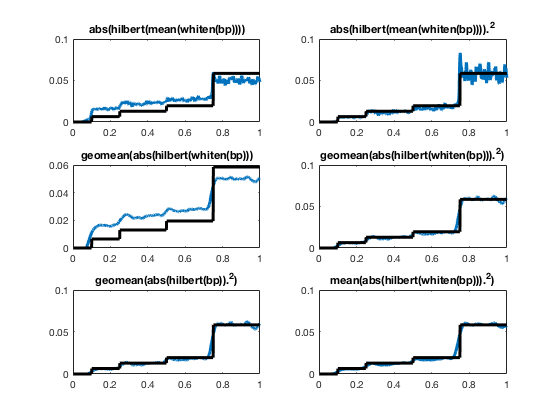

fH = figure;  set(fH, 'Color', 'w');

% clip time series to avoid edge artifacts
idx = t > 0 & t < 1;

for ii = 1:6
    subplot(3,2,ii)
    
    % Extracted broadband, averaged across trials  
    mn = geomean(broadband{ii},2);
    baseline = mn(t>-1 & t < 0);
    mn = mn(idx) - mean(baseline);
    
    % scale for plotting
    mnToPlot = mn / norm(mn);
    spikeRateToPlot = spikeRate(idx) / norm(spikeRate(idx));
    
    
    
    plot(t(idx), mnToPlot, t(idx), spikeRateToPlot, 'k-', 'LineWidth', lw)
    title(str{ii})
    set(gca, 'XLim', xl);
end